# **Mapa de Henón**

El **mapa de Henón** es un modelo matemático utilizado para estudiar sistemas dinámicos no lineales y caóticos. Fue propuesto por Michel Henón en 1976 y es una de las primeras representaciones simples de comportamiento caótico en sistemas discretos.

## **Ecuaciones del mapa de Henón**

El mapa de Henón se describe mediante un par de ecuaciones recursivas:

#### 
$$x_{n+1} =1+y_n -{a\;x}_n^2$$


#### 
$$y_{n+1} =b\;x_n$$


El mapa de Henón exhibe **caos** para ciertos valores de los parámetros $a$ y $b$. El comportamiento es altamente sensible a las condiciones iniciales, lo que es una característica del caos.

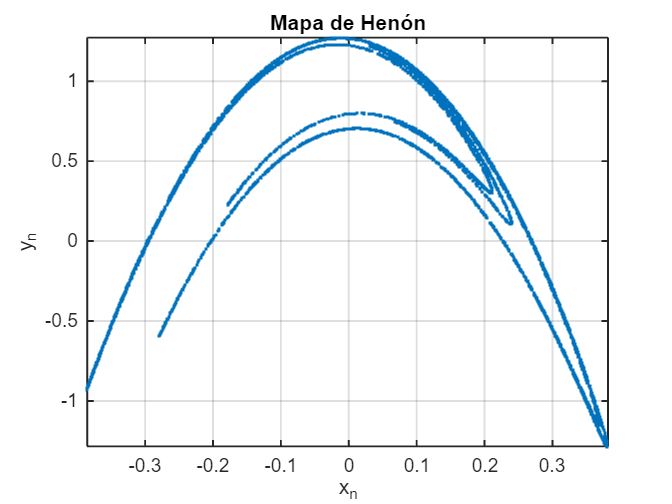


% Parámetros del mapa de Henón
a = 1.4; % Parámetro no lineal
b = 0.3; % Factor de escalado

N = 6000; % Número de iteraciones

% Condiciones iniciales
x0 = 0.1; % Valor inicial de x
y0 = 0.2; % Valor inicial de y

% Inicialización de vectores
x = zeros(N+1, 1); % Coordenada x
y = zeros(N+1, 1); % Coordenada y

% Asignación de condiciones iniciales
x(1) = x0;
y(1) = y0;

% Generación iterativa del mapa de Henón
for n = 1:N
    x(n+1) = 1 + y(n) - a * (x(n))^2; % Cálculo de x
    y(n+1) = b * x(n);                % Cálculo de y
end

% Configuración gráfica
figure;
plot(y(50:end), x(50:end), '.', 'MarkerSize', 6); % Representar resultados a partir de la iteración 50 para eliminar el regimen transitorio
title('Mapa de Henón', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('x_n', 'FontSize', 15);
ylabel('y_n', 'FontSize', 15);
grid on; % Activar cuadrícula
set(gca, 'FontSize', 12, 'LineWidth', 1.2); % Personalización de la gráfica
axis tight; % Ajustar los límites de los eje

# Sensibilidad a las condiciones iniciales

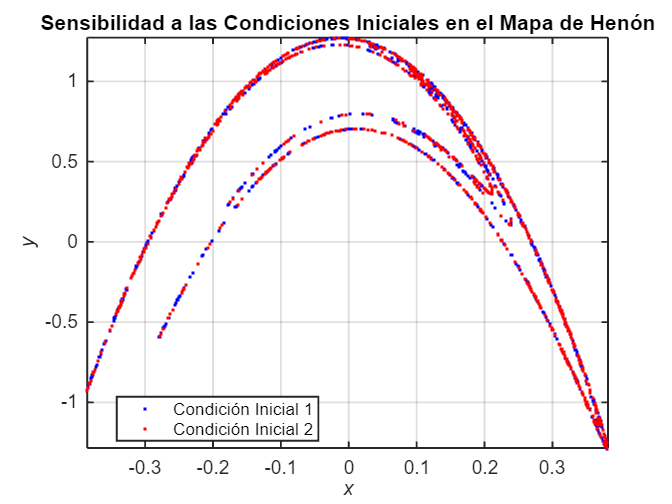

% Parámetros del mapa de Henón
a = 1.4; % Parámetro no lineal
b = 0.3; % Factor de escalado

N = 1000; % Número de iteraciones

% Condiciones iniciales
x0 = 0.1; % Valor inicial de x
y0 = 0.2; % Valor inicial de y

% Inicialización de vectores para dos condiciones iniciales

x1 = zeros(N+1, 1); % Coordenada x para la primera trayectoria
y1 = zeros(N+1, 1); % Coordenada y para la primera trayectoria

x2 = zeros(N+1, 1); % Coordenada x para la segunda trayectoria
y2 = zeros(N+1, 1); % Coordenada y para la segunda trayectoria

% Asignación de condiciones iniciales
x1(1) = x0;
y1(1) = y0;

x2(1) = x0 + 1e-9; % Condición inicial ligeramente diferente
y2(1) = y0;

% Generación de las trayectorias con las dos condiciones iniciales
for n = 1:N
    x1(n+1) = 1 + y1(n) - a * (x1(n))^2; % Cálculo de x para la primera trayectoria
    y1(n+1) = b * x1(n);                % Cálculo de y para la primera trayectoria
    
    x2(n+1) = 1 + y2(n) - a * (x2(n))^2; % Cálculo de x para la segunda trayectoria
    y2(n+1) = b * x2(n);                % Cálculo de y para la segunda trayectoria
end

% Gráficas de las trayectorias
figure;
plot(y1(50:end), x1(50:end), 'b.', 'MarkerSize', 6); hold on;
plot(y2(50:end), x2(50:end), 'r.', 'MarkerSize', 6); % Trayectoria de la segunda condición inicial
title('Sensibilidad a las Condiciones Iniciales en el Mapa de Henón', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('\itx', 'FontSize', 15);
ylabel('\ity', 'FontSize', 15);
legend({'Condición Inicial 1', 'Condición Inicial 2'}, 'Location', 'Best');
grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2); % Personalización de la gráfica
axis tight; % Ajustar los límites de los ejes

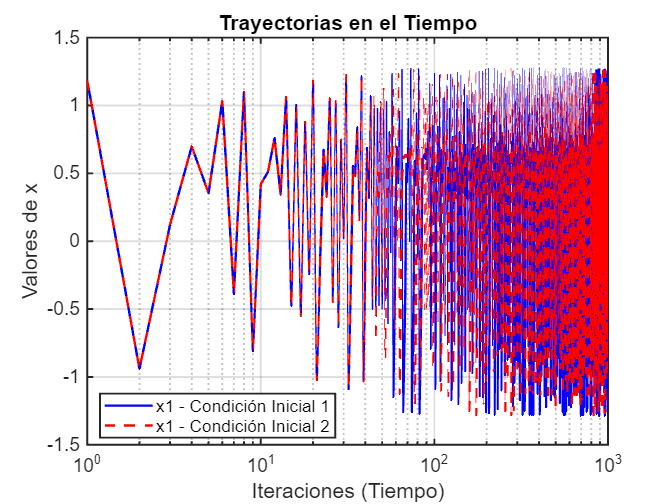

t = 0:N; % Vector de tiempo

% Trayectoria de la primera condición inicial
figure;
semilogx(t, x1, 'b-', 'LineWidth', 1.5); hold on
% Trayectoria de la segunda condición inicial
semilogx(t, x2, 'r--', 'LineWidth', 1.5); 

title('Trayectorias en el Tiempo', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('Iteraciones (Tiempo)', 'FontSize', 15);
ylabel('Valores de x', 'FontSize', 15);
legend({'x1 - Condición Inicial 1', 'x1 - Condición Inicial 2'}, 'Location', 'Best');
grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2); % Personalización de la gráfica